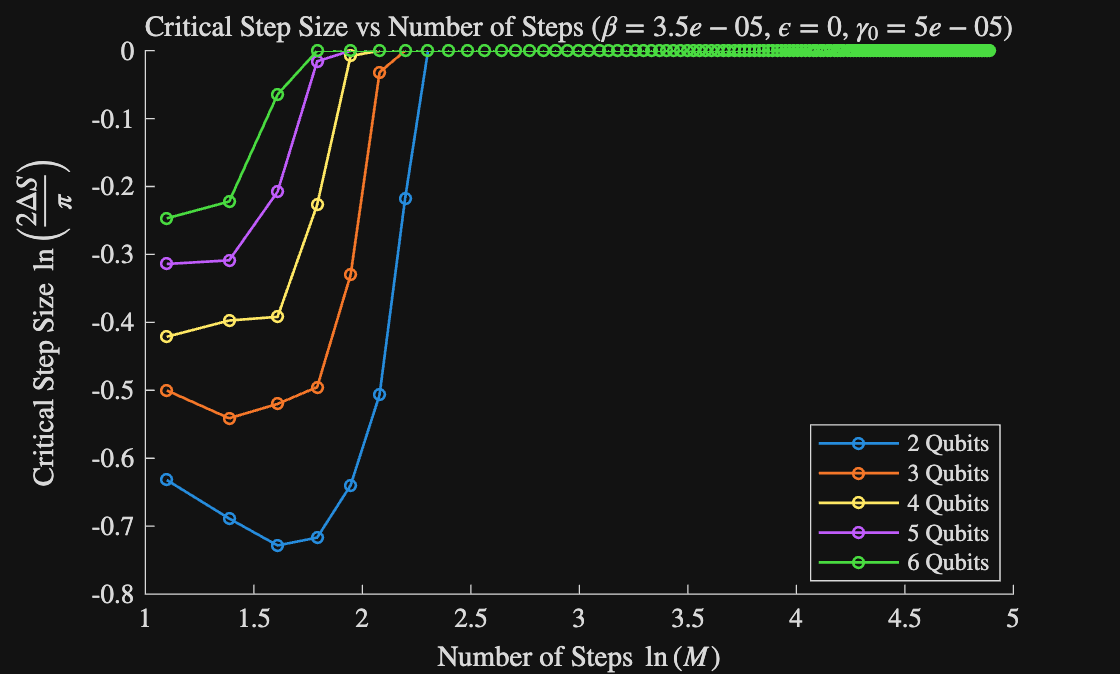

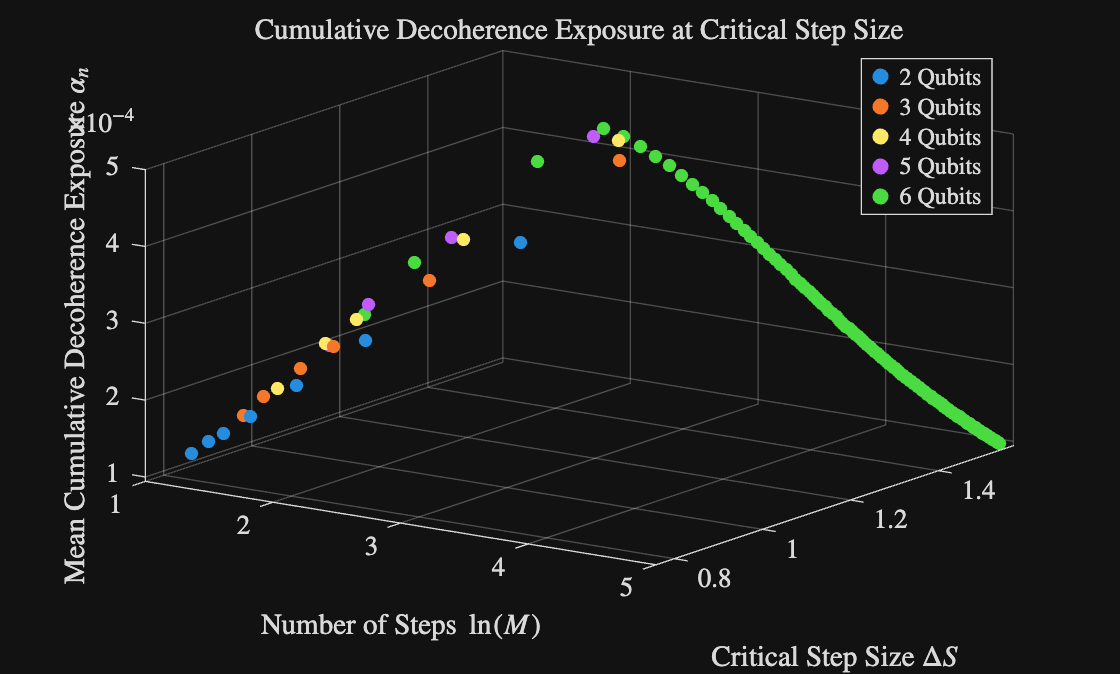

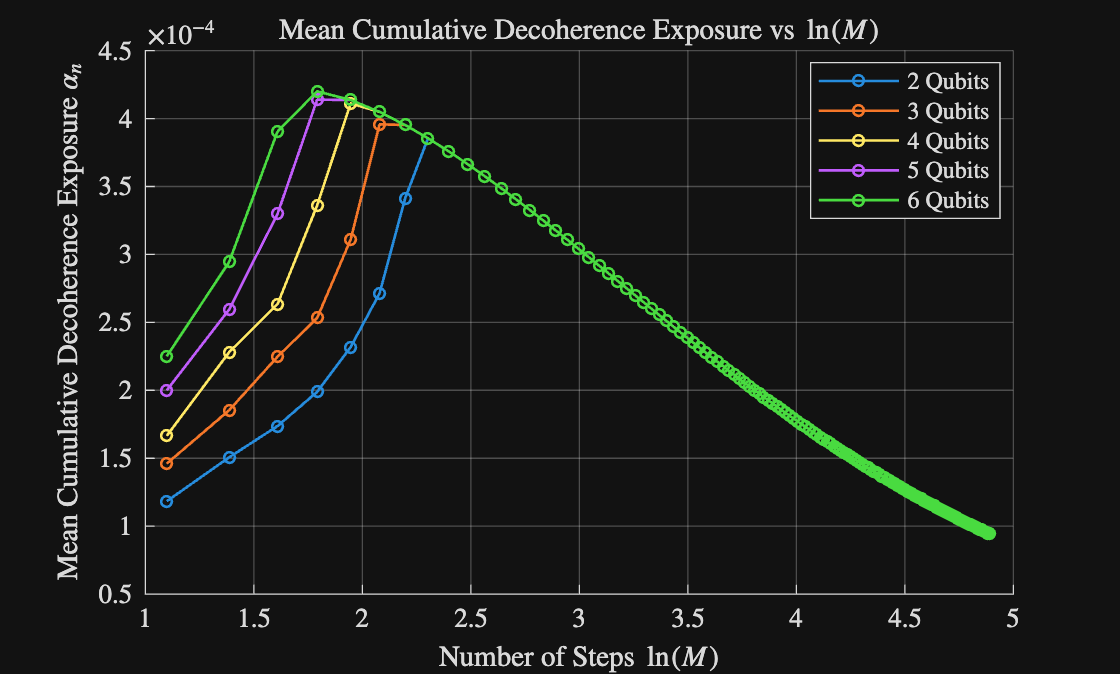

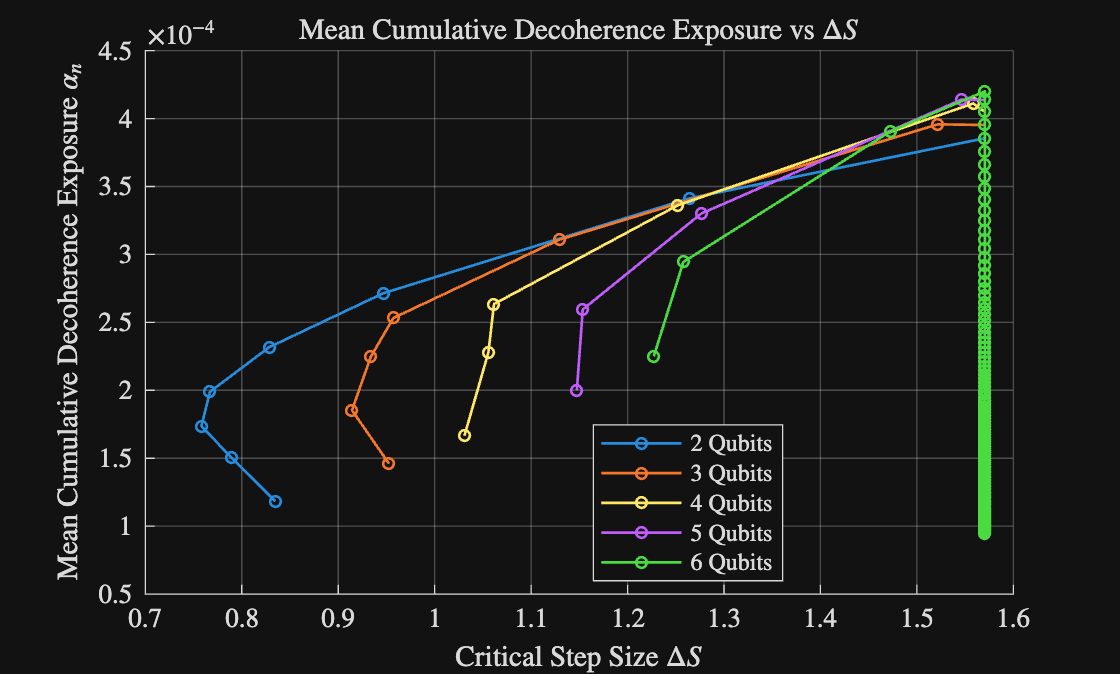

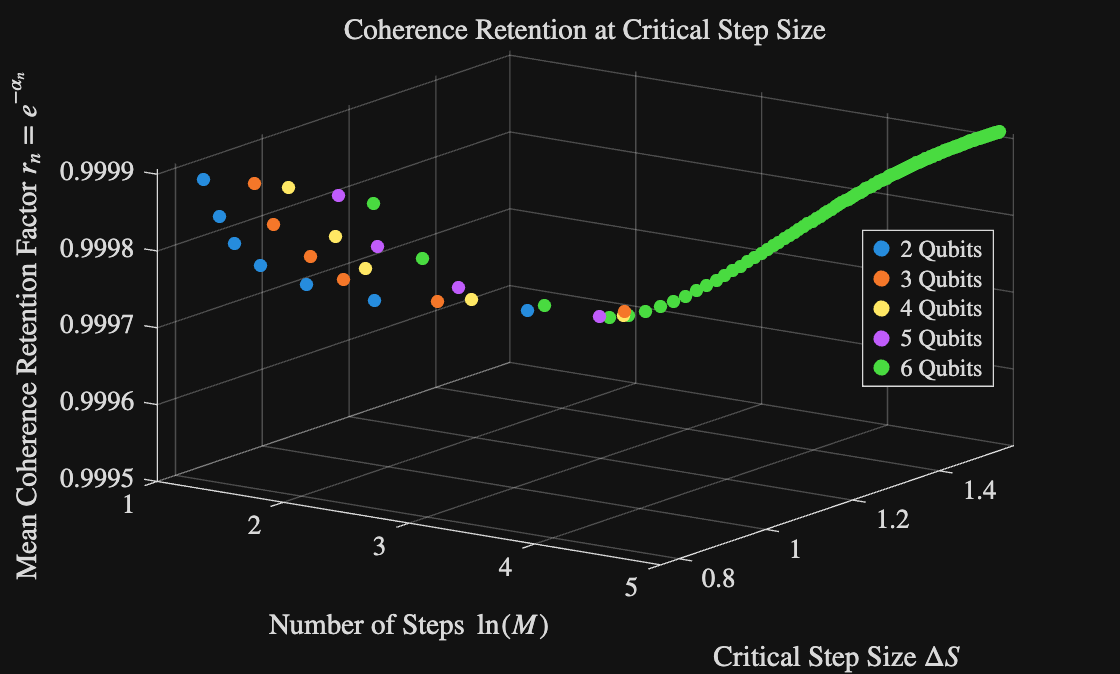

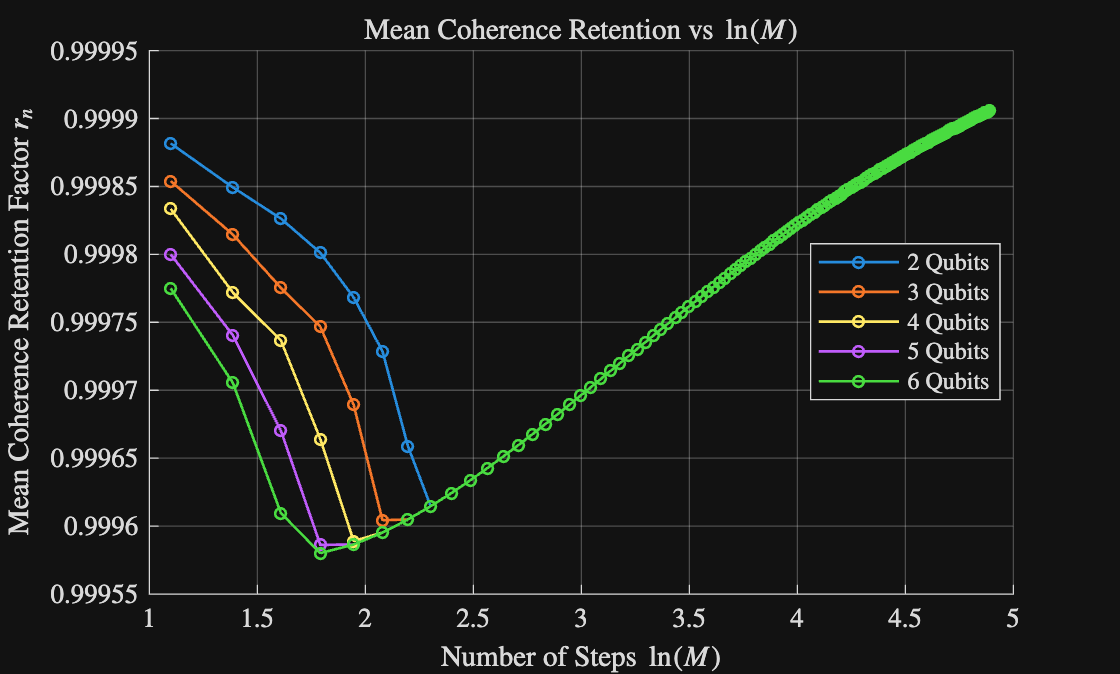

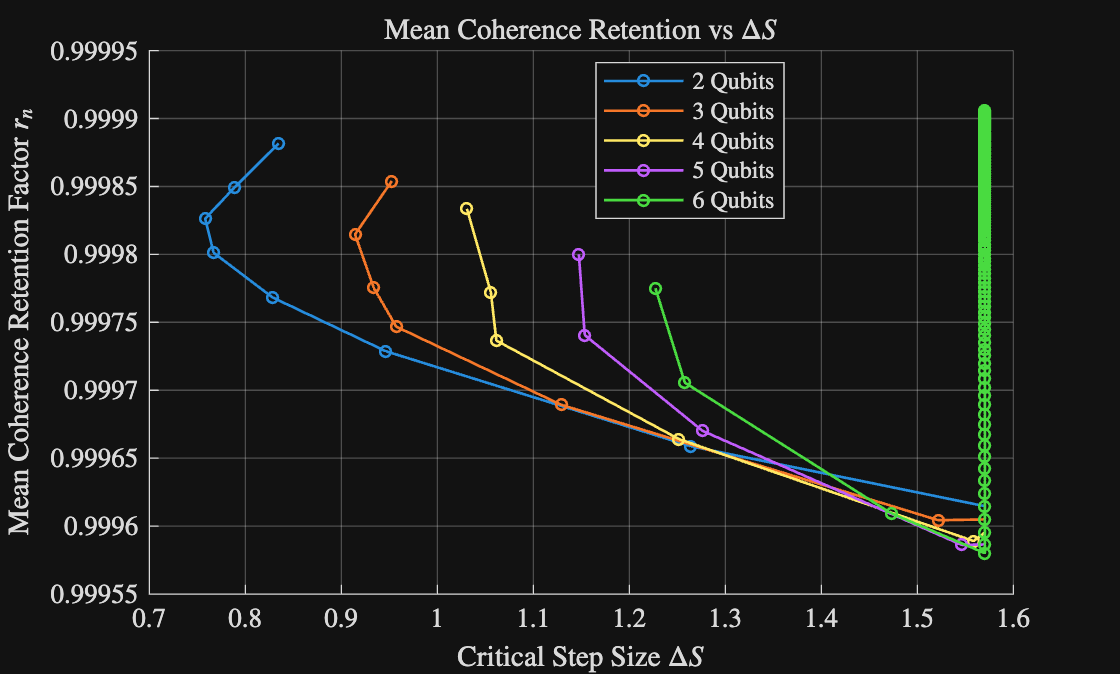

Number_of_Qubits = 6;
Number_of_Walks = 1000;

Minimum_Number_of_Steps = 3;
Maximum_Number_of_Steps = 133; 

Step_Size_Resolution = 1e-3;

Background_Decoherence = 5e-5;
Linear_Decoherence_Weighting = 3.5e-5; 
Geometric_Decoherence_Weighting = 0; 

set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Random_Walk_Plotting(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution,  Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence);

function RWP = Random_Walk_Plotting(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence)

RWP = zeros(Number_of_Qubits-1, 2);

Critical_Step_Sizes = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence);

% --- Plot 1: Critical step size vs number of steps --- %
figure;
hold on;
for j = 1:(Number_of_Qubits-1)
    plot(log(Minimum_Number_of_Steps:Maximum_Number_of_Steps), ...
         log((2/pi)*Critical_Step_Sizes(j, :)), '-o', ...
         'LineWidth', 1, 'MarkerSize', 4, ...
         'DisplayName', sprintf('%d Qubits', j+1));

    xlabel('Number of Steps $ \ln \left( M \right) $');
    ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $');
    title(sprintf('Critical Step Size vs Number of Steps ($\\beta = %.3g$, $\\epsilon = %.3g$, $\\gamma_0 = %.3g$)',Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence));
    legend('Location','best');
end
hold off;
drawnow;

% --- Compute Mean_Cumulative_Decoherence_Exposure and Number_Steps_Plotting at the critical step size for each (N,M) --- %

Number_of_Steps_Plotting = Minimum_Number_of_Steps:Maximum_Number_of_Steps;
Step_Counts = numel(Number_of_Steps_Plotting);

Mean_Cumulative_Decoherence_Exposure = zeros(Number_of_Qubits-1, Step_Counts);
Mean_Coherence_Retention_Factor = zeros(Number_of_Qubits-1, Step_Counts);

for N = 2:Number_of_Qubits
    for i = 1:Step_Counts

        [~, a, r] = Random_Walk_Algorithm(N, Number_of_Steps_Plotting(i), Number_of_Walks, Critical_Step_Sizes(N-1, i), Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence);
        
        Mean_Cumulative_Decoherence_Exposure(N-1, i) = mean(a);
        Mean_Coherence_Retention_Factor(N-1, i) = mean(r);
    end
end

% --- Plot 2: Mean cumulative decoherence exposure vs (M, critical ΔS) ---
x = log(Number_of_Steps_Plotting); 

fig3D_a = figure; hold on
fig2D_a_M  = figure; hold on
fig2D_a_dS = figure; hold on

for j = 1:(Number_of_Qubits-1)
    x = log(Number_of_Steps_Plotting);
    y = Critical_Step_Sizes(j, :);
    z = Mean_Cumulative_Decoherence_Exposure(j, :);
    name = sprintf('%d Qubits', j+1);

    figure(fig3D_a);   scatter3(x, y, z, 25, 'filled', 'DisplayName', name);
    figure(fig2D_a_M); plot(x, z, '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', name);
    figure(fig2D_a_dS);plot(y, z, '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', name);
end

figure(fig3D_a);
xlabel('Number of Steps $\ln(M)$');
ylabel('Critical Step Size $\Delta S$');
zlabel('Mean Cumulative Decoherence Exposure $\alpha_n$');
title('Cumulative Decoherence Exposure at Critical Step Size');
legend('Location','best'); grid on; view(35,25); hold off

figure(fig2D_a_M);
xlabel('Number of Steps $\ln(M)$','Interpreter','latex');
ylabel('Mean Cumulative Decoherence Exposure $\alpha_n$','Interpreter','latex');
title('Mean Cumulative Decoherence Exposure vs $\ln(M)$');
legend('Location','best'); grid on; hold off

figure(fig2D_a_dS);
xlabel('Critical Step Size $\Delta S$');
ylabel('Mean Cumulative Decoherence Exposure $\alpha_n$');
title('Mean Cumulative Decoherence Exposure vs $\Delta S$');
legend('Location','best'); grid on; hold off


% --- Plot 3: Mean coherence retention vs (M, critical ΔS) ---

fig3D_r = figure; hold on
fig2D_r_M  = figure; hold on
fig2D_r_dS = figure; hold on

for j = 1:(Number_of_Qubits-1)
    y = Critical_Step_Sizes(j, :);
    z = Mean_Coherence_Retention_Factor(j, :);
    name = sprintf('%d Qubits', j+1);

    figure(fig3D_r);   scatter3(x, y, z, 25, 'filled', 'DisplayName', name);
    figure(fig2D_r_M); plot(x, z, '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', name);
    figure(fig2D_r_dS);plot(y, z, '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', name);
end

figure(fig3D_r);
xlabel('Number of Steps $\ln(M)$');
ylabel('Critical Step Size $\Delta S$');
zlabel('Mean Coherence Retention Factor $r_n = e^{-\alpha_n}$');
title('Coherence Retention at Critical Step Size');
legend('Location','best'); grid on; view(35,25); hold off

figure(fig2D_r_M);
xlabel('Number of Steps $\ln(M)$');
ylabel('Mean Coherence Retention Factor $r_n$');
title('Mean Coherence Retention vs $\ln(M)$');
legend('Location','best'); grid on; hold off

figure(fig2D_r_dS);
xlabel('Critical Step Size $\Delta S$');
ylabel('Mean Coherence Retention Factor $r_n$');
title('Mean Coherence Retention vs $\Delta S$');
legend('Location','best'); grid on; hold off
figure;
hold on;
for j = 1:(Number_of_Qubits-1)
    y = Critical_Step_Sizes(j, :);
    z = Mean_Cumulative_Decoherence_Exposure(j, :);

    scatter3(x, y, z, 25, 'filled', 'DisplayName', sprintf('%d Qubits', j+1));
end
xlabel('Number of Steps $\ln(M)$');
ylabel('Critical Step Size $\Delta S$');
zlabel('Mean Cumulative Decoherence Exposure $\alpha_n$');
title('Cumulative Decoherence Exposure at Critical Step Size');
legend('Location','best');
grid on;
view(35,25);
hold off;

end


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence)

Data = zeros((Number_of_Qubits-1), (Maximum_Number_of_Steps - Minimum_Number_of_Steps)+1 );

for N = 2:Number_of_Qubits

    Precision = pi*0.5 - acos(1/sqrt(2^N));
    %Precision = pi*0.5 - 0.03;

    for M = Minimum_Number_of_Steps:Maximum_Number_of_Steps

        % --- Bisection Root Finding Algorithm --- %

        Lower_Bound = 0;
        Upper_Bound = pi/2;

        Critical_Step_Size = 0;

        while abs(Lower_Bound - Upper_Bound) > Step_Size_Resolution

            Midpoint = (Lower_Bound + Upper_Bound)/2;

            Midpoint_Value = Random_Walk_Algorithm(N, M, Number_of_Walks, Midpoint, Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence) - Precision;

            if abs(Midpoint_Value) <= Step_Size_Resolution
                Critical_Step_Size = Midpoint;
                break
            elseif Midpoint_Value < 0
                Upper_Bound = Midpoint;
            else
                Lower_Bound = Midpoint;
            end
        end

        if Critical_Step_Size == 0
            Critical_Step_Size = (Lower_Bound + Upper_Bound)/2;
        end

        Data(N-1,(M- (Minimum_Number_of_Steps-1))) = Critical_Step_Size;
    end
end
end


function [RWA, Cumulative_Decoherence_Exposure_Array, Coherence_Retention_Factor_Array] = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size, Linear_Decoherence_Weighting, Geometric_Decoherence_Weighting, Background_Decoherence)

Final_Distances = zeros(1, Number_of_Walks);
Cumulative_Decoherence_Exposure_Array = zeros(1, Number_of_Walks);
Coherence_Retention_Factor_Array = zeros(1, Number_of_Walks);

Dimensions = 2^Number_of_Qubits;

Pole_Vector = zeros(Dimensions, 1);
Pole_Vector(1) = 1;

Component_Volume = Number_of_Walks * Number_of_Steps;
Vector_Database = randn(Dimensions, Component_Volume) + 1i*randn(Dimensions, Component_Volume);

for i = 1:Number_of_Walks

    Anteprevious_State = Pole_Vector;
    Previous_State = Pole_Vector;
    Current_State = Pole_Vector;

    Cumulative_Decoherence_Factor = 0;
    Coherence_Retention_Factor    = 1;

    Previous_Step_Size = Step_Size;
    Previous_Decoherence_Rate = 0;

    for n = 1:2

        Step_Size = Previous_Step_Size * Coherence_Retention_Factor;
        %Step_Size = Previous_Step_Size;

        Selected_Vector = Vector_Database(:, n + (i-1)*Number_of_Steps);

        Orthogonal_Vector = Selected_Vector - dot(Current_State, Selected_Vector)*Current_State;
        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

        New_State = (cos(Step_Size) * Current_State) + (sin(Step_Size) * Normalized_Vector);

        Decoherence_Rate = Background_Decoherence + Linear_Decoherence_Weighting*(Step_Size^2);

        Cumulative_Decoherence_Factor = Cumulative_Decoherence_Factor + Previous_Decoherence_Rate * Previous_Step_Size;
        Coherence_Retention_Factor = exp(- Cumulative_Decoherence_Factor);

        Anteprevious_State = Previous_State;
        Previous_State = Current_State;
        Current_State = New_State;

        Previous_Decoherence_Rate = Decoherence_Rate;
        Previous_Step_Size = Step_Size;

    end

    for n = 3:Number_of_Steps

        Step_Size = Previous_Step_Size * Coherence_Retention_Factor;
        %Step_Size = Previous_Step_Size;

        Selected_Vector = Vector_Database(:, n + (i-1)*Number_of_Steps);

        Orthogonal_Vector = Selected_Vector - dot(Current_State, Selected_Vector)*Current_State;
        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

        New_State = (cos(Step_Size) * Current_State) + (sin(Step_Size) * Normalized_Vector);

        Phi = Bargmann_Phase(Anteprevious_State, Previous_State, New_State);

        Decoherence_Rate = Background_Decoherence + Linear_Decoherence_Weighting*(Step_Size^2) + Geometric_Decoherence_Weighting*(Phi^2);

        Cumulative_Decoherence_Factor = Cumulative_Decoherence_Factor + Previous_Decoherence_Rate * Previous_Step_Size;
        Coherence_Retention_Factor = exp(-Cumulative_Decoherence_Factor);

        Anteprevious_State = Previous_State;
        Previous_State = Current_State;
        Current_State = New_State;

        Previous_Decoherence_Rate = Decoherence_Rate;
        Previous_Step_Size = Step_Size;

    end

    Final_Distances(i) = Fubini_Study_Distance(Pole_Vector, Current_State);

    Cumulative_Decoherence_Exposure_Array(i) = Cumulative_Decoherence_Factor;
    Coherence_Retention_Factor_Array(i) = Coherence_Retention_Factor;

end

RWA = pi*0.5 - mean(Final_Distances);

% Average_Cumulative_Decoherence = mean(Cumulative_Decoherence_Exposure_Array);
% Average_Coherence_Retention = mean(Coherence_Retention_Factor_Array);

end


function Bargmann_Phase = Bargmann_Phase(State_1, State_2, State_3)

Bargmann_Invariant = dot(State_1, State_2) * dot(State_2, State_3) * dot(State_3, State_1);
Bargmann_Phase = angle(Bargmann_Invariant);
   
end


function FBS = Fubini_Study_Distance(Vector_1, Vector_2)
FBS = acos(abs(dot(Vector_1, Vector_2)));
end